# **矩形波导中的场分布 **

**        TE10模是矩形波导中最常用的一种模式，它具有最低的截止频率和最长的截止波长，因此称其为矩形波导的基模。当工作频率**$$$f>f_{c(TE_{10})}$$$**时,波导中只传输TE10模，即实现单模传输。对于矩形波导的主模TE10模，电磁场分量瞬时值形式为如下**


$$\begin{array}{l}
E_x (x,y,z,t)=0\\
E_y (x,y,z,t)=\frac{\omega a\mu }{\pi }H_m \sin (\frac{\pi }{a}x)\sin (\omega t-k_z z)\\
E_z (x,y,z,t)=0\\
H_x (x,y,z,t)=-\frac{a\beta }{\pi }H_m \sin (\frac{\pi }{a}x)\sin (\omega t-k_z z)\\
H_y (x,y,z,t)=0\\
H_z (x,y,z,t)=H_m \cos (\frac{\pi }{a}x)\cos (\omega t-k_z z)
\end{array}$$


**        可绘制TE10模在波导中传输的动态图**

**        是否绘制电场：**

clc
clear
E1=false;

**        是否绘制磁场：**

H1=true;

**        开始绘制：**

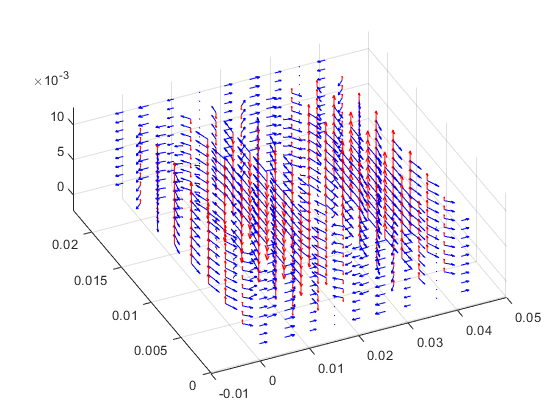

ao=22.86;
bo=10.16;          	%矩形波导尺寸，单位mm
u=4*pi*10^(-7);             	%磁导率
d=8;                      	%箭头个数
H0=1;
f=9.84*10^9;               	%工作频率
T=1/f;
t=0;
a=ao/1000;                 	%单位换算成m
b=bo/1000;                 	%单位换算成m
lamdac=2*a;                	%TE10模的截止波长
lamda0=3*10^8/f;            	%工作波长
if(lamda0>lamdac)  
    return;
else
    clf;                	%工作波长大于截止波长则模式截止，停止运算
    lamdag=lamda0/((1-(lamda0/lamdac)^2)^0.5); 	%波导波长
    c=lamdag;                  	%传输方向长度取一个波导波长
    Beta=2*pi/lamdag;           	%相移常数
    w=Beta*3*10^8;             	%角频率
    t=0;                        	%初始时刻
    x=0:a/d:a;
    y=0:b/d:b;
    z=0:c/d:c;
    [x1,y1,z1]=meshgrid(x,y,z);
    for i=1:150
        if H1
            hx=-Beta.*a.*H0.*sin(pi./a.*x1).*sin(w*t-Beta.*z1)./pi;
            hz=H0.*cos(pi./a.*x1).*cos(w*t-z1.*Beta);
            hy=zeros(size(y1));       	%磁场的三个分量赋值
            H=quiver3(z1,x1,y1,hz,hx,hy,'b');
            hold on;
        end
        if E1
            ex=zeros(size(x1));
            ey=w.*u.*a.*H0.*sin(pi./a.*x1).*sin(w*t-Beta.*z1)./pi;
            ez=zeros(size(z1));        	%电场的三个分量赋值
            E=quiver3(z1,x1,y1,ez,ex,ey,'r');
        end
        view(-25,60);
        mov(i)=getframe(gcf);
        hold on
        t=t+T*0.01;
        hold off
    end
end

- **动态展示**

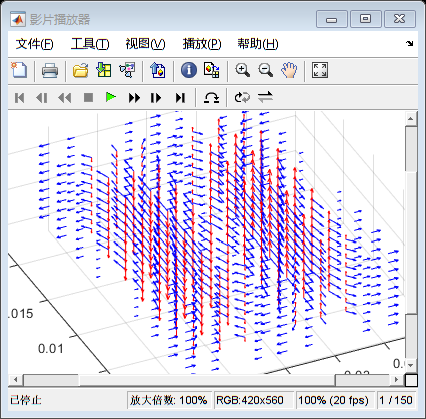

implay(mov);

- **保存为视频文件**

v=VideoWriter('矩形波导.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)
writeVideo(v,mov)
close(v)